# Taller XI

### 26/06/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 8 y 9*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

*Notas frente al uso de los métodos:*

#### *        Métodos de resolución de ecuaciones diferenciales u***nivariable**   

`        E = euler (f, a, b, ya, M)`

`            - f funcion creada con @`

`            - a y b son los extremos izquierdo y derecho`

`            - ya es la condicion inicial  y(a)`

`            - M es el numero de pasos`

`            - E = [T', Y'] donde T es el vector de abscisas y`

`                Y es el vector de ordenadas`

`        T4 = taylor (df, a, b, ya, M) `*Método de Taylor de Orden 4.*

`            - df = [y', y'', y''', y''''] funcion creada con @ donde  y' = f(t, y)`

`            - a y b son los extremos izquierdo y derecho`

`            - ya es la condicion inicial  y(a)`

`            - M es el numero de pasos`

`            - T4 = [T', Y'] donde  T  es el vector de abscisas y`

`                Y  es el vector de ordenadas`

`        H = heun (f, a, b, ya, M)`

`            - f funcion creada con @`

`            - a y b son los extremos izquierdo y derecho`

`            - ya es la condicion inicial  y(a)`

`            - M es el numero de pasos`

`            - H = [T', Y'] donde  T  es el vector de abscisas y`

`                Y es el vector de ordenadas`

`        EM = eulerMod (f, a, b, ya, M)`

`            - f funcion creada con @`

`            - a y b son los extremos izquierdo y derecho`

`            - ya es la condicion inicial  y(a)`

`            - M es el numero de pasos`

`            - EM = [T', Y'] donde  T  es el vector de abscisas y`

`                Y es el vector de ordenadas`

`        R = rk4 (f, a, b, ya, M)`

                        `- f funcion creada con @`

                        `- a y b son los extremos izquierdo y derecho`

                        `- ya es la condicion inicial  y(a)`

                        `- M es el numero de pasos`

                        `- R = [T', Y'] donde  T  es el vector de abscisas`

                        `    y  Y  es el vector de ordenadas`

### Ejemplo de aplicación

...

Con esto en mente, usemos esta herramienta para analizar un sistema físico interesante, el **pendulo doble.**

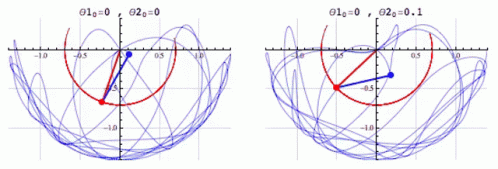

Figura 10

Este sistema es la incorporación de dos pendulos simples los cuales estan acomplados como se muestra anteriormente, realicemos el analisis de este sistema por partes, para poder establecer así una idea.

Para empezar a proceder con la propuesta del problema es necesario definir las variables a usar:

            
$$\begin{array}{l}
L\to \textrm{Lagragiano}\\
T\to \textrm{Energia}\;\textrm{total}\;\textrm{cinetica}\\
V\to \textrm{Modulo}\;\textrm{de}\;\textrm{las}\;\textrm{velocidades}\\
\theta_i \to \textrm{Angulo}\;\textrm{que}\;\textrm{describe}\;\textrm{el}\;\textrm{pendulo}\;i\\
m_i \to \textrm{Masa}\;\textrm{del}\;\textrm{pendulo}\;i\\
l_i \to \textrm{Longuitud}\;\textrm{del}\;\textrm{pendulo}\;i\\
g\to \textrm{Aceleración}\;\textrm{de}\;\textrm{la}\;\textrm{gravedad}
\end{array}$$


Primeramente realicemos el cálculo de la Lagragiana $L=T-V$, con esta podemos definir que:


$$L=\frac{1}{2}\;\left(m_1 +m_2 \right){\;l_1 }^2 \;{\left(\frac{d\theta_1 }{\textrm{dt}}\right)}^2 +m_2 \;l_1 \;l_2 \;\left(\frac{d\theta_1 }{\textrm{dt}}\right)\left(\frac{d\theta_2 }{\textrm{dt}}\right)\cos \left(\theta_1 -\theta_2 \right)+\frac{1}{2}m_2 {\;l_2 }^2 \;{\left(\frac{d\theta_2 }{\textrm{dt}}\right)}^2 +\frac{1}{2}\;\left(m_1 +m_2 \right)g\;l_1 \cos \left(\theta_1 \right)+\frac{1}{2}\;m_2 \;g\;l_2 \;\cos \left(\theta_2 \right)$$


Así obtenemos las ecuaciones del movimiento:


$$\begin{array}{l}
\frac{d}{\textrm{dt}}\;\frac{\partial L}{\partial {\theta_1 }^{\prime } }-\frac{\partial L}{\partial \theta_1 }=0\\
\left(m_1 +m_2 \right){\;l_1 }^2 \;\left(\frac{d^2 \theta_1 }{{\textrm{dt}}^2 }\right)+m_2 \;l_1 \;l_2 \;\left(\frac{d^2 \theta_2 }{{\textrm{dt}}^2 }\right)\cos \left(\theta_1 -\theta_2 \right)+m_2 \;l_1 \;l_2 \;{\left(\frac{d\theta_2 }{\textrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)+\left(m_1 +m_2 \right)\;g\;l_1 \;\sin \left(\theta_1 \right)=0
\end{array}$$



$$\begin{array}{l}
\frac{d}{\textrm{dt}}\;\frac{\partial L}{\partial {\theta_2 }^{\prime } }-\frac{\partial L}{\partial \theta_2 }=0\\
m_2 \;{l_2 }^2 \;\left(\frac{d^2 \theta_2 }{{\textrm{dt}}^2 }\right)+m_2 \;l_1 \;l_2 \;\left(\frac{d^2 \theta_1 }{{\textrm{dt}}^2 }\right)\;\cos \left(\theta_1 -\theta_2 \right)-m_2 \;l_1 \;l_2 \;{\left(\frac{d\theta_1 }{\textrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)+m_2 \;g\;l_2 \;\sin \left(\theta_2 \right)=0
\end{array}$$


Aqui proponemos dividir ambas ecuaciones por $m_2 \;l_1 \;l_2 \;$, y así llamamos $m=\frac{m_1 \;}{m_2 }$.


$$\begin{array}{l}
\left(1\right)\;\;\;\left(m+1\right)\;\frac{l_1 }{l_2 }\left(\frac{d^2 \theta_1 }{{\textrm{dt}}^2 }\right)+\left(\frac{d^2 \theta_2 }{{\textrm{dt}}^2 }\right)\cos \left(\theta_1 -\theta_2 \right)+{\left(\frac{d\theta_2 }{\textrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)+\left(m+1\right)\;\frac{g}{l_2 }\;\sin \left(\theta_1 \right)=0\\
\left(2\right)\;\;\;\frac{l_2 }{l_1 }\;\left(\frac{d^2 \theta_2 }{{\textrm{dt}}^2 }\right)+\left(\frac{d^2 \theta_1 }{{\textrm{dt}}^2 }\right)\;\cos \left(\theta_1 -\theta_2 \right)-{\left(\frac{d\theta_1 }{\textrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)+\frac{g}{l_1 }\;\sin \left(\theta_2 \right)=0
\end{array}$$


Veamos que este sistema de ecuaciones de segundo orden, podemos transformarlo en un sistema de primer orden, pero antes es necesario despejar cada una de las expresiones para poder definir el sistema, así usaremos la notación:


$$\left\lbrace \begin{array}{ll}
a_1 \frac{\;d^2 \theta_1 }{{\textrm{dt}}^2 }+b\frac{\;d^2 \theta_2 }{{\textrm{dt}}^2 }+c_1 =0 & \;\\
a_2 \frac{\;d^2 \theta_2 }{{\textrm{dt}}^2 }+b\frac{\;d^2 \theta_1 }{{\textrm{dt}}^2 }+c_2 =0 & \;
\end{array}\right.$$


Así obtenemos que:


$$\begin{array}{l}
\frac{\;d^2 \theta_1 }{{\textrm{dt}}^2 }=\frac{a_2 \;c_1 -b\;c_2 }{b^2 -a_1 \;a_2 }\\
\frac{\;d^2 \theta_2 }{{\textrm{dt}}^2 }=\frac{a_1 \;c_2 -b\;c_1 }{b^2 -a_1 \;a_2 }
\end{array}$$


Con esto proponemos que:


$$U^{\prime } :={\left\lbrack \begin{array}{c}
\theta_1 \\
{\theta_1 }^{\prime } \\
\theta_2 \\
{\theta_2 }^{\prime } 
\end{array}\right\rbrack }^{\prime } =\left\lbrack \begin{array}{c}
{\theta_1 }^{\prime } \\
\frac{\cos \left(\theta_1 -\theta_2 \right)\;\left(\frac{g}{l_1 }\sin \left(\theta_2 \right)-{\left(\frac{d\theta_1 }{\textrm{dt}}\right)}^2 \;\sin \left(\theta_1 -\theta_2 \right)\right)-\frac{l_2 }{l_1 }\left(\left(m+1\right)\frac{g}{l_2 }\sin \left(\theta_1 \right)+{\left(\frac{d\theta_2 }{\textrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)\right)}{m+\sin^2 \left(\theta_1 -\theta_2 \right)}\\
{\theta_2 }^{\prime } \\
\frac{\cos \left(\theta_1 -\theta_2 \right)\;\left(\left(m+1\right)\frac{g}{l_2 }\sin \left(\theta_1 \right)+{\left(\frac{d\theta_2 }{\textrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)\right)-\left(m+1\right)\frac{l_2 }{l_1 }\left(\frac{g}{l_1 }\sin \left(\theta_2 \right)+{\left(\frac{d\theta_1 }{\textrm{dt}}\right)}^2 \sin \left(\theta_1 -\theta_2 \right)\right)}{m+\sin^2 \left(\theta_1 -\theta_2 \right)}
\end{array}\right\rbrack$$


Veamos que para este sistema tenemos las herramientas para poder afrontarlo, entonces, procederemos a hallar la aproximación a la solución con los métodos anteriormente vistos, y verificaremos con la expresión de la energia total del sistema de las 2 particulas, el cual debe ser constante. Esta expresión de energía total toma la forma $E_{\textrm{total}} =E_{\textrm{Cinetica}} +E_{\textrm{Potencial}}$, esta debe ser constante ya que trabajamos con un sistema invariante:


$$E_{\textrm{Total}} =\frac{\left(m_1 +m_2 \right)}{2}\;{l_1 }^2 \;{\left(\frac{d\theta_1 }{\textrm{dt}}\right)}^2 +\frac{m_2 }{2}\;{l_2 }^2 \;{\left(\frac{d\theta_2 }{\textrm{dt}}\right)}^2 +m_2 \;l_1 \;l_2 \;\left(\frac{d\theta_1 }{\textrm{dt}}\right)\left(\frac{d\theta_2 }{\textrm{dt}}\right)\cos \left(\theta_1 -\theta_2 \right)-\left(m_1 +m_2 \right)\;g\;l_1 \;\cos \left(\theta_1 \right)-m_2 g\;l_2 \;\cos \left(\theta_2 \right)$$


clf('reset')
clear

Propongamos para cada caso la relación de masas $m$, las longuitudes de los pendulos $l_1$ y $l_2$.

m= 1;  % relación m1/m2
L1=1;
L2=2;

Ahora si la parte vital de esta aproximación, propongamos las posiciones angulares iniciales $\theta_1$ y $\theta_2$, para este caso asumiremos que ambos pendulos parten del reposo, o sea $\frac{{d\theta }_1 }{\textrm{dt}}=\frac{{d\theta }_2 }{\textrm{dt}}=0$

Seleccionar las particiones para la aproximación inicial:

    
$$\theta_1 \left(0\right)=\frac{\pi }{M},\theta_2 \left(0\right)=\frac{\pi }{N}$$


M = 6;
N = 6;
x0 = [pi/M, 0, -pi/N, 0];
tspan = [0,25];

fg = @(t,x)[x(2);
    (cos(x(1)-x(3))*(9.8*sin(x(3))/L1-x(2)^2*sin(x(1)-x(3)))-...
    (L2*((m+1)*9.8*sin(x(1))/L2+x(4)^2*sin(x(1)-x(3)))/L1))...
    /(m+sin(x(1)-x(3))*sin(x(1)-x(3)));
    x(4);
    (cos(x(1)-x(3))*((m+1)*9.8*sin(x(1))/L2+x(4)^2*sin(x(1)-x(3)))...
    -((m+1)*L1*(9.8*sin(x(3))...
    /L1-x(2)^2*sin(x(1)-x(3)))/L2))/(m+sin(x(1)-x(3))*sin(x(1)-x(3)))];

Para la solución de este sistema usaremos el método de Runge-Kutta de Orde 4.

a = tspan(1);
b = tspan(2);
F = @(t, U) fg(t, U)';
Za = x0';
M = 750;

% Método Range-kutta
Za = Za';
h = (b - a) / M;
Z = zeros(M+1, length(Za));
T = a:h:b;
Z(1, :) = Za;

for  j = 1:M
   k1 = h * feval(F, T(j), Z(j, :));
   k2 = h * feval(F, T(j) + h/2, Z(j, :) + k1/2);
   k3 = h * feval(F, T(j) + h/2, Z(j, :) + k2/2);
   k4 = h * feval(F, T(j) + h, Z(j, :) + k3);
   Z(j+1, :) = Z(j, :) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
end

for  j = 1:3
    disp("El método de RK, en la iteración " + num2str(j) + " se obtiene que:")
   k1 = h * feval(F, T(j), Z(j, :));
   k2 = h * feval(F, T(j) + h/2, Z(j, :) + k1/2);
   k3 = h * feval(F, T(j) + h/2, Z(j, :) + k2/2);
   k4 = h * feval(F, T(j) + h, Z(j, :) + k3);
   Z(j+1, :) = Z(j, :) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
   disp("Obtenemos el vector:")
   disp(Z(j+1, :)')
end

El método de RK, en la iteración 1 se obtiene que:


Obtenemos el vector:


    0.5197
   -0.2336
   -0.5213
    0.1404



El método de RK, en la iteración 2 se obtiene que:


Obtenemos el vector:


    0.5080
   -0.4690
   -0.5142
    0.2835



El método de RK, en la iteración 3 se obtiene que:


Obtenemos el vector:


    0.4884
   -0.7082
   -0.5023
    0.4318



R = [T', Z];
x = R(:, 2:5);

Para darnos una idea básica de lo que está ocurriendo, graficaremos la representación de las trayectorias $\left(\theta_1 ,\omega_1 \right)$ y $\left(\theta_2 ,\omega_2 \right)$, tener en cuenta que para este caso $\omega_i =\frac{d\theta_i }{\textrm{dt}}$, hacemos esto para poder dejar la notación en la gráfica

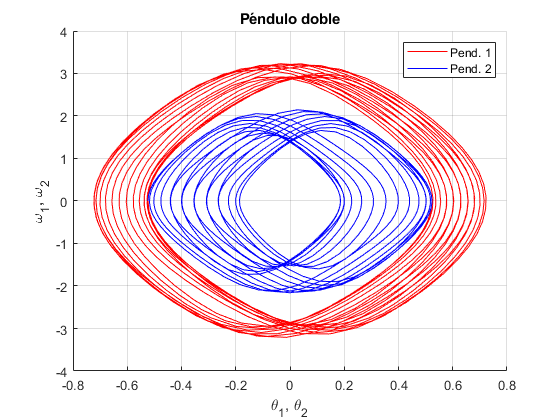

clf('reset')
hold on
plot(x(:,1),x(:,2),'r') 
plot(x(:,3),x(:,4),'b')
grid on
legend('Pend. 1','Pend. 2');
xlabel('\theta_1, \theta_2')
ylabel('\omega_1, \omega_2')
title('Péndulo doble')
hold off

Einicial=-(m+1)*9.8*cos(x0(1))/L2-9.8*cos(x0(3))/L1;

E=(m+1)*L1*x(:,2).^2/(2*L2)+L2*x(:,4).^2/(2*L1)+(x(:,2).*x(:,4))...
.*cos(x(:,1)-x(:,3))-(m+1)*9.8*cos(x(:,1))/L2-9.8*cos(x(:,3))/L1;

El error relativo que obtenemos con esta aproximación es:

ErrorRK = max(abs(100*(Einicial-E)/Einicial)) 

ErrorRK = 0.0078

Por otro lado el error que hallamos usando el método ode45.m incluido en MATLAB es:

[t,x] = ode45(fg,tspan,x0);

E=(m+1)*L1*x(:,2).^2/(2*L2)+L2*x(:,4).^2/(2*L1)+(x(:,2).*x(:,4))...
.*cos(x(:,1)-x(:,3))-(m+1)*9.8*cos(x(:,1))/L2-9.8*cos(x(:,3))/L1;

ErrorTeorico = max(abs(100*(Einicial-E)/Einicial))

ErrorTeorico = 0.5048

clear

Aquí podemos ver como los métodos que definimos en el curso pueden tener gran fuerza contra métodos que podemos encontrar por defecto con nuestras herramientas.

...

### Solución númerica de ecuaciones diferenciales ordinarias

Para el taller de esta semana se solucionan dos ejercicios: $\left.\left.\left.\left.1\right),2\right)\;4\right)\;\&\;6\right)$ del taller 12

**1) **Considere un péndulo simple de longitud$L=2p$ y suponga que la gravedad está dada por $g=32,17\;p/s^2$. Con $h=0,1s$, compare el ángulo $\theta \;$que se obtiene para los siguientes problemas de valor inicial en $t=0,1\;y\;2\;s$


$$\begin{array}{l}
\frac{d^2 \theta }{{\textrm{dt}}^2 }+\frac{g}{L}\;\sin \;\theta =0\\
\theta \left(0\right)=\frac{\pi }{6}\;,\theta^{\prime } \left(0\right)=0
\end{array}$$


Para afrontar estos tipos de ejercicios es necesario realizar la siguiente aclaración:

    Toda ecuación de $n$ grado es el resultado del sistema de ecuaciones diferenciales $n\;x\;n$ de ecuaciones de primer grado, así veamos que podemos reescribir:


$$\frac{d^n x}{{\textrm{dt}}^n }+a_{n-1} \;\frac{d^{n-1} x}{{\textrm{dt}}^{n-1} }\ldotp \ldotp \ldotp +\;{a\;}_0 \;x=0\;\;\to {\left\lbrack \begin{array}{c}
\frac{d^{n-1} x}{{\textrm{dt}}^{n-1} }\\
\frac{d^{n-2} x}{{\textrm{dt}}^{n-2} }\\
\vdots \\
x
\end{array}\right\rbrack }^{\prime } =-\left\lbrack \begin{array}{c}
a_{n-1} \;\frac{d^{n-1} x}{{\textrm{dt}}^{n-1} }\ldotp \ldotp \ldotp +\;{a\;}_0 \;x\\
\frac{d^{n-1} x}{{\textrm{dt}}^{n-1} }\\
\vdots \\
\frac{\textrm{dx}}{\textrm{dt}}
\end{array}\right\rbrack$$


O sea veamos que el sistema de ecuaciones que representa nuestro problema inicial es:


$$\frac{d^2 \theta }{{\textrm{dt}}^2 }+\frac{g}{L}\;\sin \;\theta =0\;\to {\left\lbrack \begin{array}{c}
\frac{d\theta }{\textrm{dt}}\\
\theta 
\end{array}\right\rbrack }^{\prime } =\left\lbrack \begin{array}{c}
-\frac{g}{L}\;\sin \;\theta \\
\frac{d\theta }{\textrm{dt}}
\end{array}\right\rbrack$$


Con esto en mente desarrollemos el sistema:

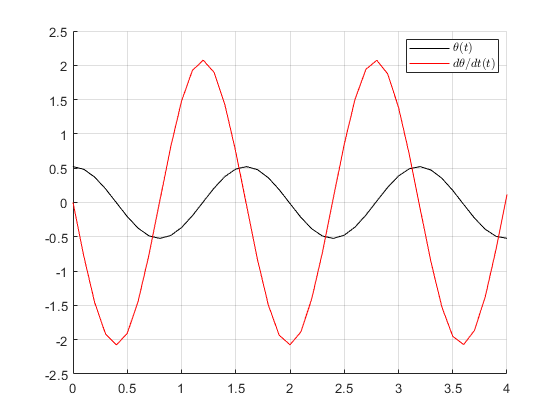

clear

% Inicializamos variables
L = 2; g = 32.17; h = .1; Ua = [pi/6 0];

% Declaramos el sistema
F = @(t, U) [U(2), - g/L * sin(U(1))];
t0 = 0; tf = round(sqrt(g/L)); % Hallemos el comportamiento de 2 oscilaciones completas
M = (tf - t0) / h;

[t, Theta] = rks4(F, t0, tf, Ua, M); % Implementamos el método
ThetaBefore = Theta(:, 1); % Guardamos el valor de Theta para compararlo posteriormente

% Conozcamos el comportamiento de estas funciones
clf('reset')
hold on
plot(t, Theta(:, 1), 'k', 'DisplayName', '$\theta(t)$')
plot(t, Theta(:, 2), 'r', 'DisplayName', '$d\theta/dt(t)$')
legend('Location','best', 'Interpreter','latex')
grid on
hold off

Veamos como varian estos valores a medida que cambiamos los valores iniciales:

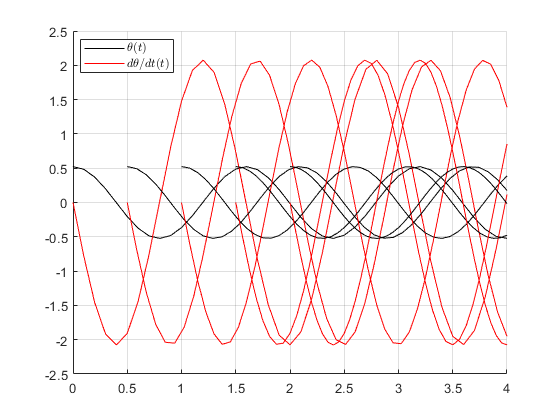

clf('reset')
hold on

% Generamos el ciclo para obtener distintos valores iniciales
for t0 = 0:.5:2
    [t, Theta] = rks4(F, t0, tf, Ua, M); % Resolvemos iterativamente el sistema

    plot(t, Theta(:, 1), 'k')
    plot(t, Theta(:, 2), 'r')
end

legend('$\theta(t)$', '$d\theta/dt(t)$', 'Location','best', 'Interpreter','latex')
grid on
hold off

El valor $t_0$ veamos que nos genera desfases en las soluciones.

Ahora consideremos la linealización del problema:


$$\begin{array}{l}
\frac{d^2 \theta }{{\textrm{dt}}^2 }+\frac{g}{L}\;\theta =0\\
\theta \left(0\right)=\frac{\pi }{6}\;,\theta^{\prime } \left(0\right)=0
\end{array}$$


De igual forma desarrollamos la ecuación linealizada:

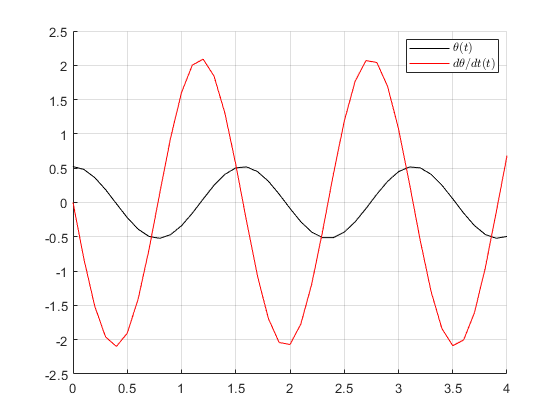

% Inicializamos variables
L = 2; g = 32.17; h = .1; Ua = [pi/6 0];

% Declaramos el sistema
F = @(t, U) [U(2), - g/L * U(1)];
t0 = 0; tf = round(sqrt(g/L)); % Hallemos el comportamiento de 2 oscilaciones completas
M = (tf - t0) / h;

[t, Theta] = rks4(F, t0, tf, Ua, M); % Implementamos el método
ThetaAfter = Theta(:, 1); % Guardamos el valor de Theta para compararlo posteriormente

% Conozcamos el comportamiento de estas funciones
clf('reset')
hold on
plot(t, Theta(:, 1), 'k', 'DisplayName', '$\theta(t)$')
plot(t, Theta(:, 2), 'r', 'DisplayName', '$d\theta/dt(t)$')
legend('Location','best', 'Interpreter','latex')
grid on
hold off

Veamos como varian estos valores a medida que cambiamos los valores iniciales:

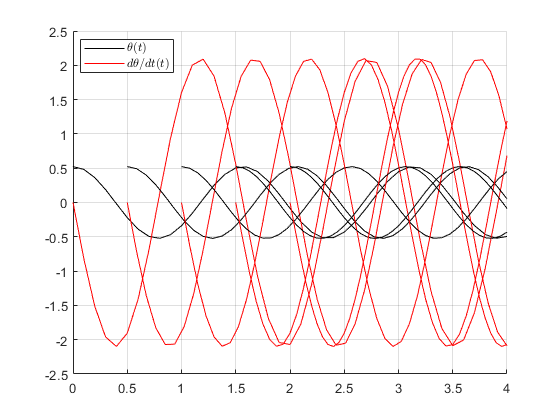

clf('reset')
hold on

% Generamos el ciclo para obtener distintos valores iniciales
for t0 = 0:.5:2
    [t, Theta] = rks4(F, t0, tf, Ua, M); % Resolvemos iterativamente el sistema

    plot(t, Theta(:, 1), 'k')
    plot(t, Theta(:, 2), 'r')
end

legend('$\theta(t)$', '$d\theta/dt(t)$', 'Location','best', 'Interpreter','latex')
grid on
hold off

Comparemos el error que existen entre ambas aproximaciones:

ErrorCuadrado = norm(ThetaAfter - ThetaBefore)^2

ErrorCuadrado = 0.1315

Un erro de aproximación considerablemente pequeño

**2) **Resorte sin amortiguación: Use el método de RK4 para sistemas para resolver el siguiente problema que corresponde a un resorte que mantiene constante su amplitud, grafique sus resultados.


$$\begin{array}{l}
{y^{\prime } }^{\prime } \;+\;192y=0\;\\
y\left(0\right)=\;\frac{1}{6},y^{\prime } \left(0\right)=0
\end{array}$$


Homologamente a lo visto anteriormente resolvemos:

clear

% Inicializamos variables
Ua = [1/6 0];

% Creemos la posibilidad interactiva de variar el valor de M,
%  para ver los cambios de resolución
M = 75

M = 75

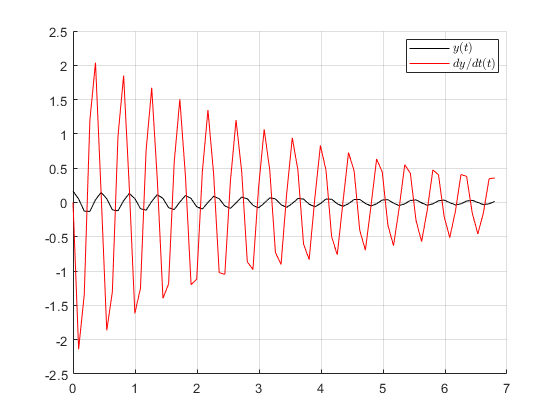

% Declaramos el sistema
F = @(t, U) [U(2), - 192 * U(1)];
t0 = 0; tf = 15* 2*pi/sqrt(192); % Hallemos el comportamiento de 15 oscilaciones completas

[t, Y] = rks4(F, t0, tf, Ua, M); % Implementamos el método

% Conozcamos el comportamiento de estas funciones
clf('reset')
hold on
plot(t, Y(:, 1), 'k', 'DisplayName', '$y(t)$')
plot(t, Y(:, 2), 'r', 'DisplayName', '$dy/dt(t)$')
legend('Location','best', 'Interpreter','latex')
grid on
hold off

Veamos que a medida que alteramos el número de pasos presentes durante las iteraciones, el comportamiento de las funciones se ven alterados, *¿Por qué sucederá esto?*

**4) **Un resorte resonante con función de forzamiento periódica se modela por medio de la ecuación diferencial ordinaria de segundo orden.


$$\begin{array}{l}
{x^{\prime } }^{\prime } \left(t\right)\;+\;25x\left(t\right)=8\;\sin \left(5t\right)\;\\
x\left(0\right)=0,x^{\prime } \left(0\right)=0
\end{array}$$


Veamos que el sistema forzado presenta un compotamiento similar, y se vuelve un problema interesante

clear

% Inicializamos variables
Ua = [0 0];

% Creemos la posibilidad interactiva de variar el valor de M,
%  para ver los cambios de resolución
M = 750

M = 750

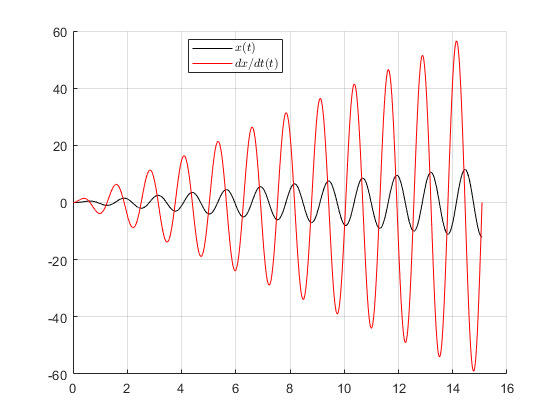

% Declaramos el sistema
F = @(t, U) [U(2), 8*sin(5*t) - 25*U(1)];
t0 = 0; tf = 12 * 2*pi/5; % Hallemos el comportamiento de 12 oscilaciones completas

[t, X] = rks4(F, t0, tf, Ua, M); % Implementamos el método

% Conozcamos el comportamiento de estas funciones
clf('reset')
hold on
plot(t, X(:, 1), 'k', 'DisplayName', '$x(t)$')
plot(t, X(:, 2), 'r', 'DisplayName', '$dx/dt(t)$')
legend('Location','best', 'Interpreter','latex')
grid on
hold off

**6) Modelo predador-presa:** Sean $x\left(t\right)$ y $y\left(t\right)$ las poblaciones de conejos y de zorros respectivamente en un tiempo t. El modelo predador-presa consiste en el sistema de ecuaciones diferenciales ordinarias

$x^{\prime } \left(t\right)=A\;x\left(t\right)-B\;x\left(t\right)\;y\left(t\right)$    **(1)**

$y^{\prime } \left(t\right)=C\;x\left(t\right)\;y\left(t\right)-D\;y\left(t\right)$    **(2)**

donde los parámetros tienen el siguiente significado:

***    A: ****Tasa de crecimiento de los conejos.*

***    B: ****Tasa de muerte de los conejos, que depende tanto de la población de*

*    conejos como de la población de zorros.*

***    C: ****Tasa de crecimiento de los zorros, la cual depende de ambas especies.*

***    D: ****Tasa de muerte de los zorros.*

Considere los siguientes conjuntos de parámetros:

**a) **$A=2,\;\;\;B=0,02,\;\;\;C=0,0002,\;\;\;D=0,8$

**a) **$A=1,\;\;\;B=1,\;\;\;C=1,\;\;\;D=1$

Resuelva el sistema por el método de Runge-Kutta de cuarto orden en el intervalo $\left\lbrack 0,10\right\rbrack$con $M=50$

con las siguientes condiciones iniciales:

**a)** $x\left(0\right)=3000\;\textrm{conejos},y\left(0\right)=120\;\textrm{zorros}$

**b)** $x\left(0\right)=5000\;\textrm{conejos},y\left(0\right)=100\;\textrm{zorros}$

Presente sus soluciones por medio de diagramas de fase.

Para esta situación, generaremos diagramas de fase para el primer conjunto de parametros, evaluaremos el comportamiento de las poblaciones, evaluaremos la primera fase, y luego variando las condiciones generales generaremos distintas fases, para ver bien los comportamientos, haremos caso omiso al valor de $M=50$, y asumiremos $M=200$.

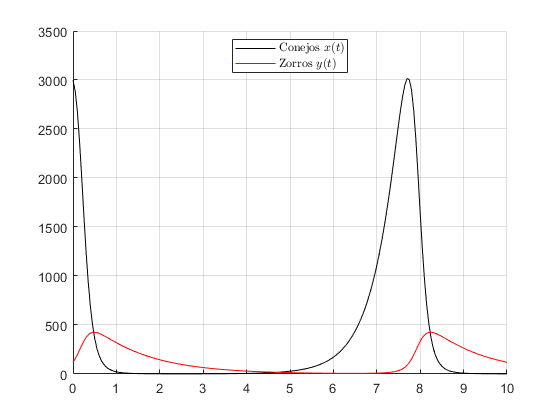

clear

% Inicializamos variables
A = 2; B = 2E-2; C = 2E-3; D = 8E-1;

% Declaramos el sistema
F = @(t, U) [A*U(1) - B*U(1)*U(2), C*U(1)*U(2) - D*U(2)];
t0 = 0; tf = 10; M = 200; Ua = [3e3 12e1];

[t, U] = rks4(F, t0, tf, Ua, M); % Implementamos el método

% Conozcamos el comportamiento de estas funciones
clf('reset')
hold on
plot(t, U(:, 1), 'k', 'DisplayName', 'Conejos $x(t)$')
plot(t, U(:, 2), 'r', 'DisplayName', 'Zorros $y(t)$')
legend('Location','best', 'Interpreter','latex')
grid on
hold off

El comportamiento es claro, a medida que incrementa la población de zorros, la población de conejos se compromete, y el decaimiento de conejos compromete la vida de los zorros.

Ahora veamos este comportamiento en un diagrama de fase:

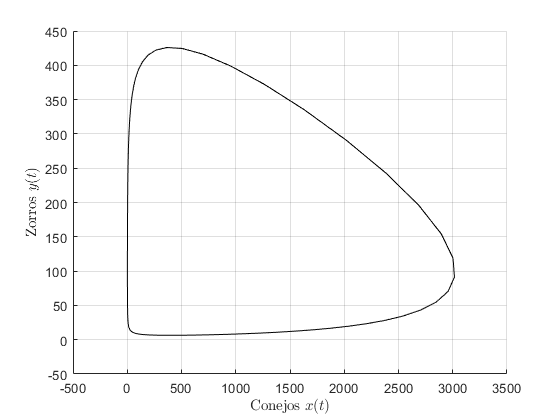

% Conozcamos el comportamiento de las fases
clf('reset')
hold on
plot(U(:, 1), U(:, 2), 'k')
xlabel('Conejos $x(t)$', 'Interpreter','latex')
ylabel('Zorros $y(t)$', 'Interpreter','latex')
xlim([-500 3500])
ylim([-50 450])
grid on
hold off

Veamos que este es el diagrama de fase para el caso particular, veamos como este cambia a medida que se alteran las condiciones iniciales:

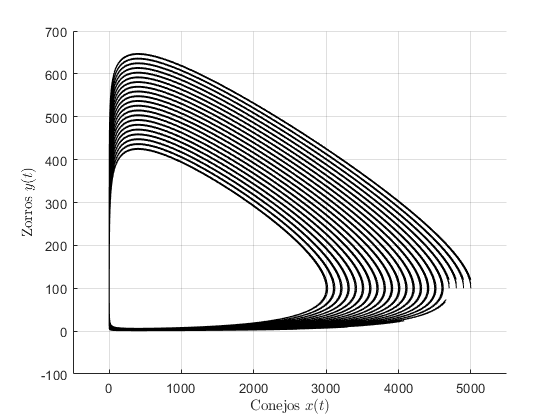

clf('reset')
hold on

% Generamos el ciclo para obtener distintos valores iniciales
for x0 = 3e3:100:5e3
    for y0 = 120:-10:100
        
        Ua = [x0, y0];
        [t, U] = rks4(F, t0, tf, Ua, 1e3); % Resolvemos iterativamente el sistema

        plot(U(:, 1), U(:, 2), 'k')
    end
end

xlabel('Conejos $x(t)$', 'Interpreter','latex')
ylabel('Zorros $y(t)$', 'Interpreter','latex')
xlim([-500 5500])
ylim([-100 700])
grid on
hold off

Este es el diagrama de fases para la ecuación diferencial tras la variación de parametros, está representa la variación de poblaciones con respecto a sus poblaciones iniciales, veamos como esta varia tras la variación de parametros:

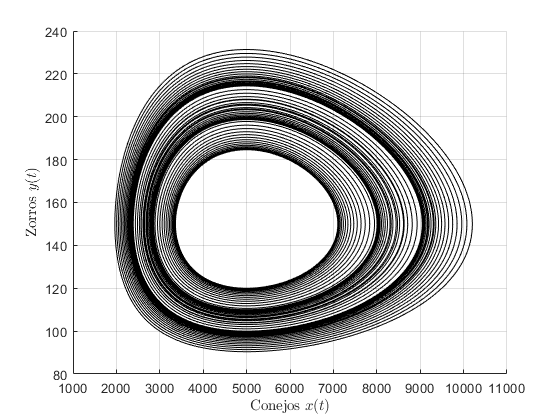

clear
% Inicializamos variables
A = 3;
B = 0.02;
C = 0.0002;
D = 1;

% Declaramos el sistema
F = @(t, U) [A*U(1) - B*U(1)*U(2), C*U(1)*U(2) - D*U(2)];
t0 = 0; tf = 10; M = 200; Ua = [3e3 12e1];

clf('reset')
hold on

% Generamos el ciclo para obtener distintos valores iniciales
for x0 = 3e3:100:5e3
    for y0 = 120:-10:100
        
        Ua = [x0, y0];
        [~, U] = rks4(F, t0, tf, Ua, 1e3); % Resolvemos iterativamente el sistema

        plot(U(:, 1), U(:, 2), 'k')
    end
end

xlabel('Conejos $x(t)$', 'Interpreter','latex')
ylabel('Zorros $y(t)$', 'Interpreter','latex')
grid on
hold off